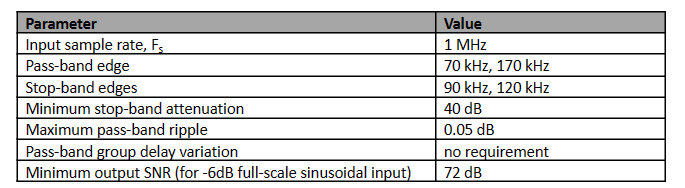

%Requirements
fs = 1e6;
fp1 = 70e3;
fp2 = 170e3;
fs1 = 90e3;
fs2 = 120e3;
Atten = 40;
PBRipple = 0.05;
SNR = 72;

wp1 = 2*fp1/fs

wp1 = 0.1400

wp1 = wp1 * pi;

wp2 = 2*fp2/fs

wp2 = 0.3400

wp2 = wp2 * pi;

ws1 = 2*fs1/fs

ws1 = 0.1800

ws1 = ws1 * pi;

ws2 = 2*fs2/fs

ws2 = 0.2400

ws2 = ws2 * pi;


wc = 0.1 *pi; %arbitrary
lambda=(cos((wp2+wp1)/2))/(cos((wp2-wp1)/2));

%% BandStop
p = tan((wp2-wp1)/2)*tan(wc/2);
ws1_hat = abs(2*atan(p*sin(ws1)/(cos(ws1)-lambda)))/pi;
ws1_hat = ws1_hat *pi;
ws2_hat = abs(2*atan(p*sin(ws2)/(cos(ws2)-lambda)))/pi;
ws2_hat = ws2_hat *pi;

%% chose more stringent stopband freq
if ws1<ws2
    ws_hat = ws1_hat;
else
    ws_hat = ws2_hat;
end

wp_hat = wc;

%%prewarp
omega_p = tan(wp_hat/2);
omega_s = tan(ws_hat/2);

%finding minimum order number to meet Passband Ripple and Attenuation
syms x
eqn = 20*log10(sqrt(1+x^2)) == PBRipple;
epsilon = double(solve(eqn));
epsilon = epsilon(1);
eqn = 20*log10(x) == Atten;
A = double(solve(eqn));

k = omega_p/omega_s;
k1 = epsilon/(sqrt(A^2-1));
k1 = k1(1);
N = acosh(1/k1)/acosh(1/k); 
N = ceil(N)

N = 6

fc = 100e3; %arbitrary

wt = [wp1/pi wp2/pi];
wo = fc/(fs/2);

order = N;
bits_min = log2(order/(2*epsilon));
bits_min = ceil(bits_min);
bits = bits_min + 5

bits = 10

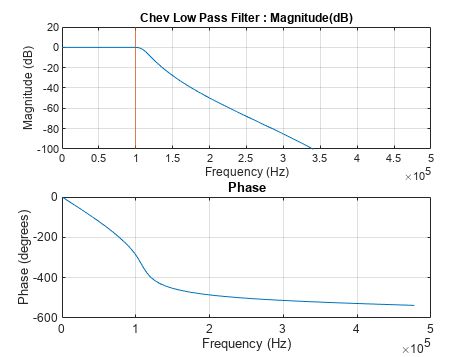

%chev filter

[b,a] = cheby1(order,PBRipple,wo);
freqz(b,a,[],fs)
xline(fc,Color=[0.8500 0.3250 0.0980])
title("Chev Low Pass Filter : Magnitude(dB)")
subplot(2,1,1)
ylim([-100 20])

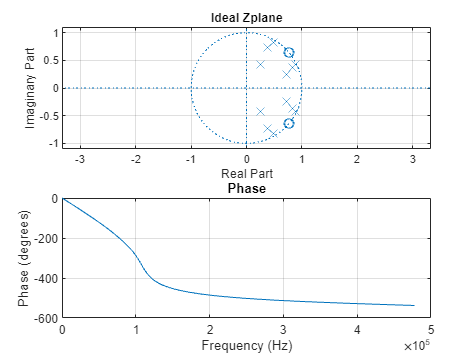


%Ideal Filter
[num,den] = iirlp2bs(b,a,wo,wt);

%Quantized Filter
bq = a2dT(b,bits); aq = a2dT(a,bits);
[numq,denq] = iirlp2bs(bq,aq,wo,wt);

%Frequency Response
hfvt = fvtool(num,den,numq,denq);
hfvt.Fs = fs;
hfvt.NumberTitle = 'on';
hfvt.FrequencyScale =  'Log';
legend(hfvt,"Ideal","Quantized")

%Poles and Zeros Plot
zplane(num,den)
grid
title("Ideal Zplane");

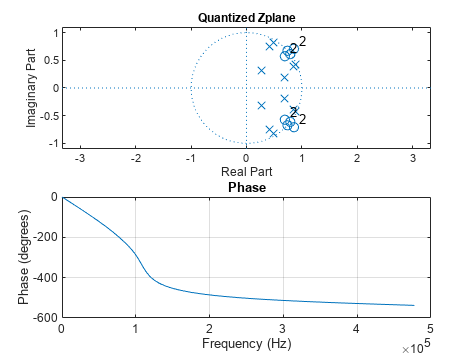

zplane(numq,denq)
title("Quantized Zplane");


%Impulse Response 
impfvt = fvtool(num,den,numq,denq,'Analysis','impulse');
legend(impfvt,"Ideal","Quantized");
impfvt.SpecifyLength = 'Specified';
impfvt.Length = 100;

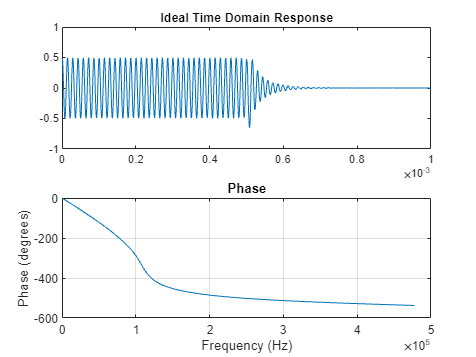

%Time Domain Simulation
samples = 1000; % Number of signal samples
t = (0:samples-1)/fs;              % Time vector
w = 2*pi*70e3;
input_sinusoid = Signal*sin(w*t);
% plot(t,input_sinusoid), grid on, ylim([-1 1])
imp = [1; zeros(samples-1,1)];
h = filter(num,den,imp);
% stem(0:samples-1,h);
w = conv(input_sinusoid,h,'same');
plot(t,w), ylim([-1 1]), title("Ideal Time Domain Response");

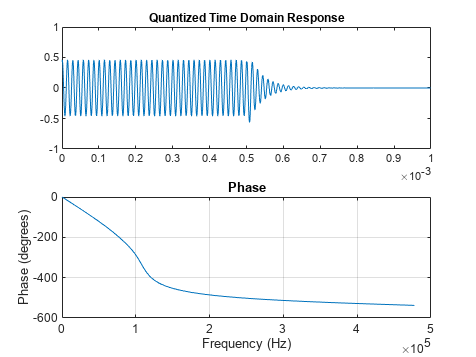

hq = filter(numq,denq,imp);
% stem(0:samples-1,hq);
wq = conv(input_sinusoid,hq,'same');
plot(t,wq), ylim([-1 1]), title("Quantized Time Domain Response");

%Hardware Calculations
adder_gatecount = bits*4;
multiplier_gatecount = 2*bits^2;
register_gatecount = 5*bits;

syms P
power_consumption = (adder_gatecount + multiplier_gatecount + register_gatecount)*P

$$power\_consumption = 290\,P$$

syms x
SNR = 72;
eqn = -6 - 20*log10(x) == 72;
Noise = double(solve(eqn))

Noise = 1.2589e-04

eqn = 20*log10(x) == -6;
Signal = double(solve(eqn))

Signal = 0.5012

invar = Signal^2/2 %variance of a sinusoid

invar = 0.1256


%9.5.4  Propagation of Input Qunatization Noise to Digital Filter Output
%9.5.5  Algebraic Computation of Output Noise Variance
%9.5.6 Computation of Output Noise Variance using MATLAB
% num = [0.06891975 0.13808186 0.18636107 0.13808186 0.068218751]
% den = [1.0 -1.30613249 1.48301305 -0.77709026 0.2361457]

[r,p,K] = residue(num,den)

r =    0.0256 + 0.0046i
   0.0256 - 0.0046i
   0.0092 + 0.0487i
   0.0092 - 0.0487i
  -0.0745 + 0.0747i
  -0.0745 - 0.0747i
   0.1762 - 0.1101i
   0.1762 + 0.1101i
  -0.1281 - 0.3397i
  -0.1281 + 0.3397i


p =    0.8776 + 0.4314i
   0.8776 - 0.4314i
   0.4909 + 0.8220i
   0.4909 - 0.8220i
   0.8375 + 0.3719i
   0.8375 - 0.3719i
   0.3848 + 0.7323i
   0.3848 - 0.7323i
   0.7297 + 0.2369i
   0.7297 - 0.2369i


K = 0.2566

R = size(r,1);
R2 = size(K,1);
    if R2 > 1
        disp('Cannot continue...')
        return;
    end

    if R2 == 1
        nvar = K^2;
    else
        nvar = 0;
    end

for k = 1:R
    for m = 1:R
        integral = r(k)*conj(r(m))/(1-p(k)*conj(p(m)));
        nvar = nvar+integral;
    end
end
disp('Output Noise Variance = '); disp(real(nvar))

Output Noise Variance = 
    0.8168



outvar = nvar

outvar = 0.8168 - 0.0000i


SNR = 10*log10(invar/outvar)

SNR = -8.1314 + 0.0000i

num = 1

den =     1.0000   -0.8100


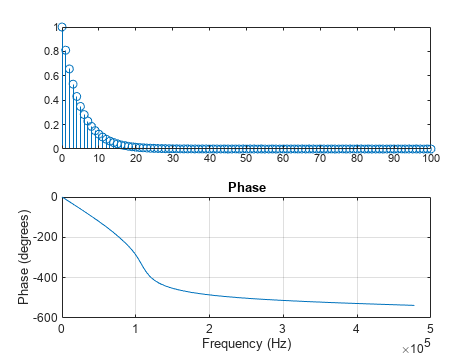

$$F = -\frac{1}{\frac{81}{100\,z}-1}$$

$$ans = {\left(\frac{81}{100}\right)}^{n}$$

num = 1

den = [1 -0.9^2]
imp = [1; zeros(100,1)];
h = filter(num,den,imp);
stem(0:100,h)


syms z
F = 1/(1-0.81*z^-1)
iztrans(F)